clc, clear all
Fs = 150; % Sampling frequency
t = 0:1/Fs:1; % Time vector of 1 second

% Define fundamental frequency (f) of the square wave
f = 10; 


x = sin(2*pi*t*f);

% Add higher order odd harmonics (3rd, 5th, ...)
a = input('Enter number of harmonics: ')

a = 40

b = 1 + 2*a;
for n = 3:2:b % Loop through odd harmonics up to 29th
  harmonic_freq = f * n;
  % Add harmonic with smaller amplitude as n increases
  x = x + (1/(n)) * sin(2*pi*t*harmonic_freq);
end

nfft = 1024; % Length of FFT


y = fft(x)

y =   -0.0000 + 0.0000i   0.0022 - 0.1081i   0.0093 - 0.2222i   0.0219 - 0.3497i   0.0418 - 0.5011i   0.0725 - 0.6941i   0.1208 - 0.9624i   0.2028 - 1.3828i   0.3662 - 2.1798i   0.8370 - 4.4174i  15.4069 -72.9815i  -1.2400 + 5.3231i  -0.6624 + 2.5977i  -0.4753 + 1.7144i  -0.3803 + 1.2684i  -0.3208 + 0.9944i  -0.2788 + 0.8064i  -0.2474 + 0.6701i  -0.2257 + 0.5743i  -0.2269 + 0.5438i  -0.7398 + 1.6740i   0.0129 - 0.0276i   0.0047 - 0.0096i   0.0411 - 0.0792i   0.0994 - 0.1822i   0.1833 - 0.3201i   0.3081 - 0.5130i   0.5106 - 0.8112i   0.8956 - 1.3594i   1.9193 - 2.7854i  13.1621 -18.2755i  -3.6985 + 4.9163i  -1.8244 + 2.3229i  -1.2897 + 1.5736i  -1.0387 + 1.2148i  -0.8967 + 1.0057i  -0.8124 + 0.8738i  -0.7702 + 0.7946i  -0.7796 + 0.7715i  -0.9208 + 0.8741i  -2.5803 + 2.3494i   0.4417 - 0.3857i   0.0464 - 0.0388i  -0.0071 + 0.0057i   0.0192 - 0.0147i   0.0939 - 0.0691i   0.2235 - 0.1575i   0.4442 - 0.2994i   0.8654 - 0.5573i   1.9325 - 1.1884i


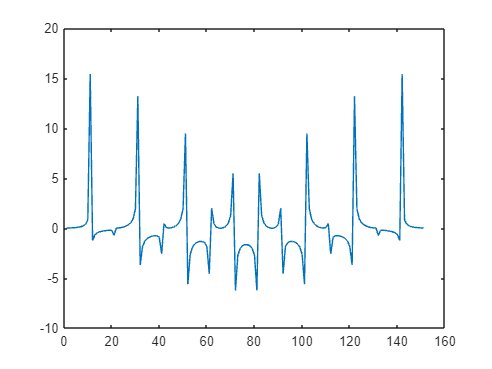

plot(real(y))

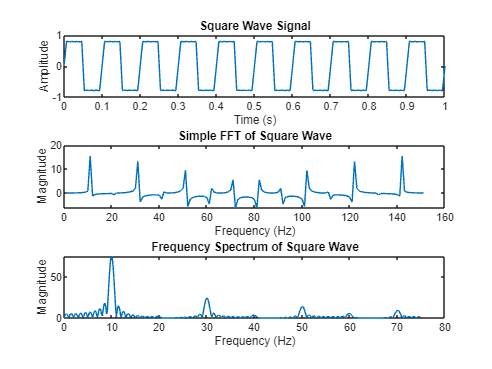

% Take FFT, padding with zeros
X = fft(x, nfft);

% Extract single-sided magnitude
X = X(1:nfft/2);
mag_x = abs(X);

% Frequency vector
f = (0:nfft/2-1)*Fs/nfft;

% Plot time domain signal
figure(1);
subplot(3,1,1)
plot(t, x);
title('Square Wave Signal');
xlabel('Time (s)');
ylabel('Amplitude');

subplot(3,1,2)
plot(real(y))
title('Simple FFT of Square Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

% Plot frequency domain (magnitude spectrum)
subplot(3,1,3)
plot(f, mag_x);
title('Frequency Spectrum of Square Wave');
xlabel('Frequency (Hz)');
ylabel('Magnitude');